# Лабораторная работа №5 по СУвЭ

## Параметрический синтез и исследование цифровой системы управления с объектом в виде двух последовательно включенных апериодических звеньев первого порядка из условия обеспечения заданного по качеству переходного процесса.

Определяем вариант задания:

% ob.R = 10+unifrnd(-1,1);
% ob.L = 0.02+unifrnd(-0.01,0.01);
% ob.J = 100+unifrnd(-10,10);
% ob.Ce = 2;
% ob.Cm = ob.Ce;
% save('data.mat', 'ob');
load('data.mat')

## Задание 1. Синтез системы с использованием «метода переоборудования»

### а) Передаточная функция объекта управления

syms ia ua w e M
syms R L J Ce
syms dia dw
eq(1) = L*dia+ R*ia==ua-e;
eq(2) = J*dw==M;
eq(3) = e==Ce*w;
eq(4) = M==Ce*ia;

S1 = solve(eq,[dia dw e M]);
disp(collect(S1.dia, [ia w ua]))

$$\left(-\frac{R}{L}\right)\,\mathrm{ia}+\left(-\frac{\mathrm{Ce}}{L}\right)\,w+\frac{\mathrm{ua}}{L}$$

disp(collect(S1.dw, [ia w ua]))

$$\frac{\mathrm{Ce}}{J}\,\mathrm{ia}$$

A = [-R/L -Ce/L;
    Ce/J 0;];
B=[1/L; 0];
C = [0 1];
D = [0];

syms s
Wwa = C*(s*eye(2) - A)^-1*B + D;
disp(collect(Wwa, s))

$$\frac{\mathrm{Ce}}{\left(J\,L\right)\,s^{2}+\left(J\,R\right)\,s+{\mathrm{Ce}}^{2}}$$

syms T1 T2 Kob
Wsmp = Kob/(T1*s+1)/(T2*s+1)

$$Wsmp = \frac{\mathrm{Kob}}{\left(T_{1}\,s+1\right)\,\left(T_{2}\,s+1\right)}$$

disp(collect(expand(Wsmp),s))

$$\frac{\mathrm{Kob}}{\left(T_{1}\,T_{2}\right)\,s^{2}+\left(T_{1}+T_{2}\right)\,s+1}$$

eqn(1) = T1*T2 ==J*L/Ce^2;
eqn(2) = T1+T2 ==J*R/Ce^2;
S2 = solve(eqn, [T1,T2]);
S2.T1

$$ans = \left(\begin{array}{c} \frac{J\,R}{{\mathrm{Ce}}^{2}}-\frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}+J\,R}{2\,{\mathrm{Ce}}^{2}}\\ \frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}-J\,R}{2\,{\mathrm{Ce}}^{2}}+\frac{J\,R}{{\mathrm{Ce}}^{2}} \end{array}\right)$$

S2.T2

$$ans = \left(\begin{array}{c} \frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}+J\,R}{2\,{\mathrm{Ce}}^{2}}\\ -\frac{\sqrt{-J\,\left(4\,{\mathrm{Ce}}^{2}\,L-J\,R^{2}\right)}-J\,R}{2\,{\mathrm{Ce}}^{2}} \end{array}\right)$$

Найдем постоянные времени

ob.T1 = -(sqrt(-ob.J*(4*ob.Ce^2*ob.L - ob.J*ob.R^2)) - ob.J*ob.R)/(2*ob.Ce^2);
ob.T2 = (sqrt(-ob.J*(4*ob.Ce^2*ob.L - ob.J*ob.R^2)) + ob.J*ob.R)/(2*ob.Ce^2);
disp(ob.T1)

    0.0022



disp(ob.T2)

  260.7847



ob.kdw = 180/pi;
ob.Kob = ob.kdw/ob.Ce

ob = struct with fields:
      R: 9.5570
      L: 0.0209
      J: 109.1501
     Ce: 2
     Cm: 2
     T1: 0.0022
     T2: 260.7847
    kdw: 57.2958
    Kob: 28.6479


### б) Расчет регулятора скорости

syms Tu
T1=Tu

$$T1 = \mathrm{Tu}$$

Wob = Kob/(T1*s+1)/(T2*s+1)

$$Wob = \frac{\mathrm{Kob}}{\left(T_{2}\,s+1\right)\,\left(\mathrm{Tu}\,s+1\right)}$$

wol = 1/(2*Tu*s*(Tu*s+1));
Wreg = wol/Wob;
disp(simplify(collect(Wreg, s)))

$$\frac{T_{2}\,s+1}{2\,\mathrm{Kob}\,\mathrm{Tu}\,s}$$

### в) Моделирование работы системы, настроенной на тех. оптиум

T0=0.1*Tu

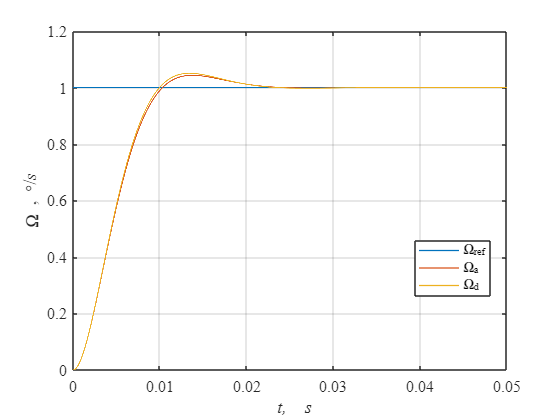

spl.Tu=ob.T1;
To = 0.1*spl.Tu;
spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);
Tmdl = 0.05;
warning off
simNew = sim('lab5_1.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t = simNew.w(:,1);
w_ref = simNew.w(:,2);
wd_sens = simNew.w(:,4);

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 4.0*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 6.3*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 5.0*Tu 


T0=1*Tu

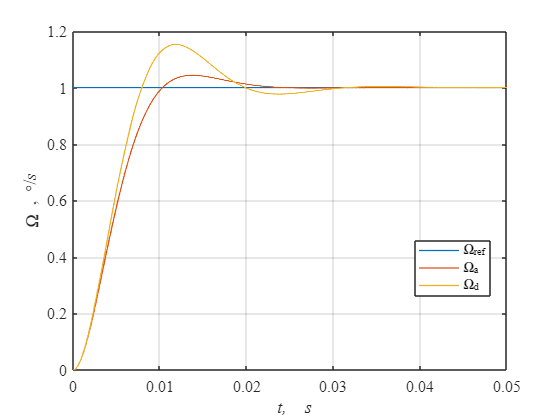

spl.Tu=ob.T1;
To = 1*spl.Tu;
spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);
Tmdl = 0.05;
warning off
simNew = sim('lab5_1.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t = simNew.w(:,1);
w_ref = simNew.w(:,2);
wd_sens = simNew.w(:,4);

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.4*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 7.8*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 15.3*Tu 


### Задание 2. Синтез системы из условия получения в ней стандартной настройки на «оптимум по модулю» с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового регулятора для случая Т1 ≈ Т0, Т2 >> Т0 , ε = 0

### а) Аппроксимация апериодическим звеном

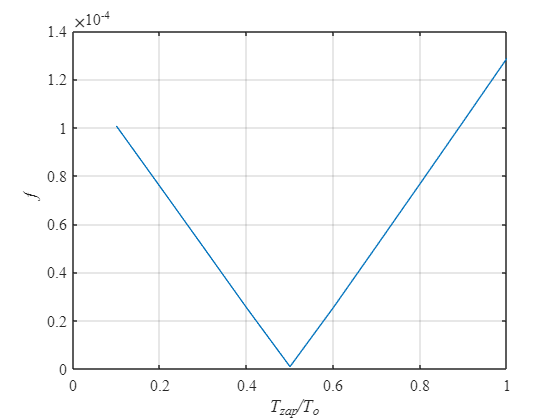

clear f Tzap
Tmdl = 1;
for i = 1:10
    spl.Tz=i/10*To;
    Tzap(i) = spl.Tz;
    warning off
    warning off
    b = sim('lab5_2.slx','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));

end

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'Linewidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

### б) Синтез цифрового ПИ-регулятора

T0=0.1*Tu

Tmdl = 1;
To = 1*ob.T1;
spl.Tz = 0.5*To

spl = struct with fields:
       Tu: 0.0022
      Kpa: 2.0775e+03
      Kia: 7.9665
      Kpd: 2.0775e+03
      Kid: 7.9665
       Tz: 0.0011
      Tur: 2.1908e-04
     Kpa2: 1
     Kda2: 0.0022
    Kd2dg: 4.5167
    Kp2dg: 1
     Kia1: 20.9645
     Kia2: 1.6418e+06
     Kiia: 6.2955e+03
     Kid1: 20.9645
     Kid2: 1.6418e+06
     Kiid: 6.2955e+03


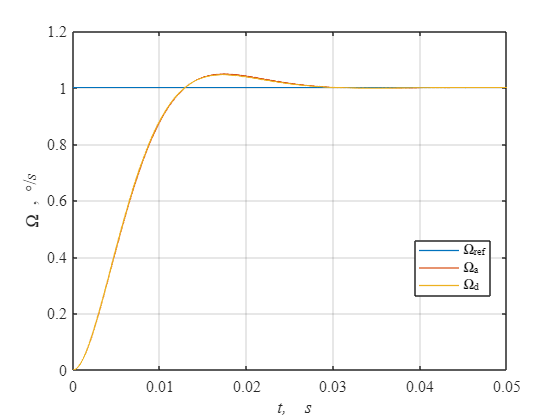

spl.Tu = ob.T1 + spl.Tz;


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);
Tmdl = 0.05;
warning off
simNew = sim('lab5_2.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t = simNew.w(:,1);
w_ref = simNew.w(:,2);
wd_sens = simNew.w(:,4);

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.5*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 3.5*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 4.5*Tu 


T0=2*Tu

To = 2*ob.T1;
spl.Tz = 0.5*To

spl = struct with fields:
       Tu: 0.0033
      Kpa: 1.3850e+03
      Kia: 5.3110
      Kpd: 1.3850e+03
      Kid: 5.3110
       Tz: 0.0022
      Tur: 2.1908e-04
     Kpa2: 1
     Kda2: 0.0022
    Kd2dg: 4.5167
    Kp2dg: 1
     Kia1: 20.9645
     Kia2: 1.6418e+06
     Kiia: 6.2955e+03
     Kid1: 20.9645
     Kid2: 1.6418e+06
     Kiid: 6.2955e+03


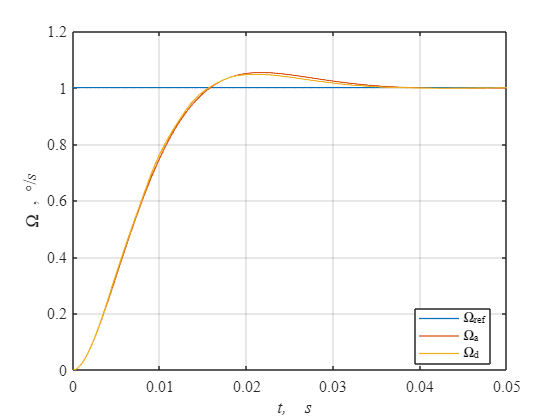

spl.Tu = ob.T1 + spl.Tz;
spl.Tu
spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);
Tmdl = 0.05;
warning off
simNew = sim('lab5_2.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t = simNew.w(:,1);
w_ref = simNew.w(:,2);
wd_sens = simNew.w(:,4);

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.1*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 3.1*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 4.8*Tu 


### Задание 3. Синтез системы из условия получения в ней стандартной настройки на «оптимум по модулю» с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового регулятора для случая Т1 >> Т0, Т2 >> Т0 , ε = 0

### а) Расчет регулятора скорости

syms Tu T1
Wob = Kob/(T1*s+1)/(T2*s+1)

$$Wob = \frac{\mathrm{Kob}}{\left(T_{1}\,s+1\right)\,\left(T_{2}\,s+1\right)}$$

wol = 1/(2*Tu*s*(Tu*s+1));
Wreg = wol/Wob;
disp(simplify(collect(Wreg, s)))

$$\frac{\left(T_{1}\,s+1\right)\,\left(T_{2}\,s+1\right)}{2\,\mathrm{Kob}\,\mathrm{Tu}\,s\,\left(\mathrm{Tu}\,s+1\right)}$$

### б) Моделирование работы системы, настроенной на тех. оптиум

T0=0.1*T1

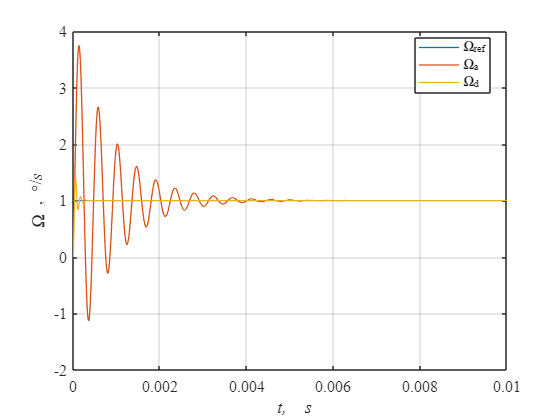

Tmdl = 0.01;

To = 0.01*ob.T1;
spl.Tur = 0.5*To;
spl.Tu = spl.Tur;


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpa2 = 1;
spl.Kda2 = ob.T1;


spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);
spl.Kd2dg = 1/(exp(To/ob.T1)-1);
spl.Kp2dg = 1;

warning off
simNew = sim('lab5_3.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t = simNew.w(:,1);
w_ref = simNew.w(:,2);
wd_sens = simNew.w(:,4);

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.0*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 16.9*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 41.6*Tu 


### в) Аппроксимация апериодическим звеном

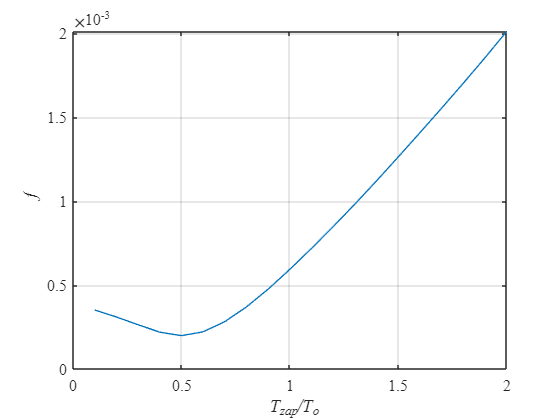

Tmdl = 0.01;
for i = 1:20
    spl.Tz=i/10*To;
    Tzap(i) = spl.Tz;
    warning off
    warning off
    b = sim('lab5_3_1.slx','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));

end

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'Linewidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

### г) Синтез цифрового регулятора скорости методом переоборудование

T0=0.1*T1

Tmdl = 0.01;

To = 0.1*ob.T1;
spl.Tz = 0.5*To

spl = struct with fields:
       Tu: 1.6431e-04
      Kpa: 2.7701e+04
      Kia: 106.2200
      Kpd: 2.7701e+04
      Kid: 106.2200
       Tz: 1.0954e-04
      Tur: 1.6431e-04
     Kpa2: 1
     Kda2: 0.0022
    Kd2dg: 6.1792
    Kp2dg: 1
     Kia1: 20.9645
     Kia2: 1.6418e+06
     Kiia: 6.2955e+03
     Kid1: 20.9645
     Kid2: 1.6418e+06
     Kiid: 6.2955e+03


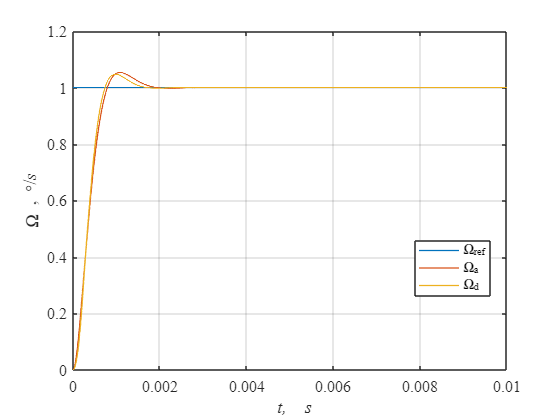

spl.Tur = 0.5*To;
spl.Tu = spl.Tur+spl.Tz;


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpa2 = 1;
spl.Kda2 = ob.T1;


spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);
spl.Kd2dg = 1/(exp(To/ob.T1)-1);
spl.Kp2dg = 1;

warning off
simNew = sim('lab5_3_1.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t = simNew.w(:,1);
w_ref = simNew.w(:,2);
wd_sens = simNew.w(:,4);

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.0*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 3.0*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 4.7*Tu 


## Задание 4. Синтез системы из условия получения в ней стандартной настройки на «оптимум по модулю» с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового регулятора для случая Т1 >> Т0, Т2 >> Т0 , ε = Т0

### а) Аппроксимация апериодическим звеном

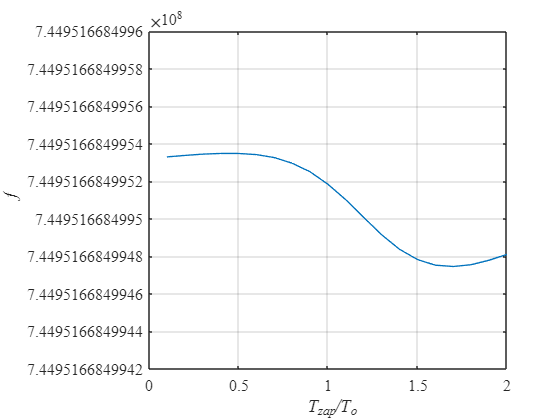

clear f Tzap
To = 0.01*ob.T1;
Tmdl = 0.01;
for i = 1:20
    spl.Tz=i/10*To;
    Tzap(i) = spl.Tz;
    warning off
    b = sim('lab5_4.slx','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));

end

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(Tzap/To,f,'Linewidth', 1)
hold on
grid on
xlabel('\it T_{zap}/T_o')
ylabel('\it f')

### б) Синтез цифрового регулятора скорости методом переоборудование

T0=0.1*T1

Tmdl = 0.01;

To = 0.1*ob.T1;
spl.Tz = 1.5*To %Значение по графику функционала

spl = struct with fields:
       Tu: 4.3817e-04
      Kpa: 1.0388e+04
      Kia: 39.8325
      Kpd: 1.0388e+04
      Kid: 39.8325
       Tz: 3.2863e-04
      Tur: 1.0954e-04
     Kpa2: 1
     Kda2: 0.0022
    Kd2dg: 9.5083
    Kp2dg: 1
     Kia1: 20.9645
     Kia2: 1.6418e+06
     Kiia: 6.2955e+03
     Kid1: 20.9645
     Kid2: 1.6418e+06
     Kiid: 6.2955e+03


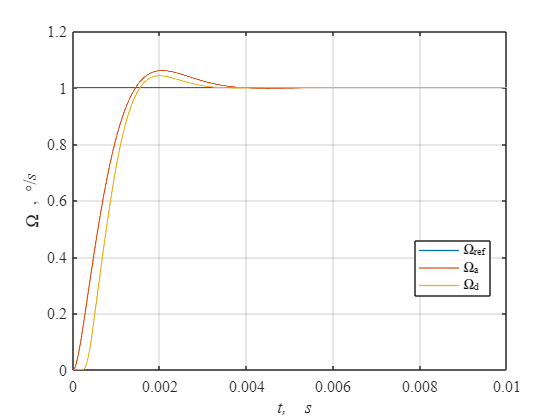

spl.Tur = 0.5*To;
spl.Tu = spl.Tur+spl.Tz;


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia = 1/(2*ob.Kob*spl.Tu);

spl.Kpa2 = 1;
spl.Kda2 = ob.T1;


spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid = 1/(2*ob.Kob*spl.Tu);
spl.Kd2dg = 1/(exp(To/ob.T1)-1);
spl.Kp2dg = 1;

warning off
simNew = sim('lab5_4.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t = simNew.w(:,1);
w_ref = simNew.w(:,2);
wd_sens = simNew.w(:,4);

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 3.1*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 3.1*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 4.1*Tu 


## Задание 5. Синтез системы из условия получения в ней стандартной настройки на«симметричный оптимум» с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового регулятора для случая Т1 ≈ Т0, Т2 >> Т0 , ε = 0

### а) Расчет регулятора скорости

### 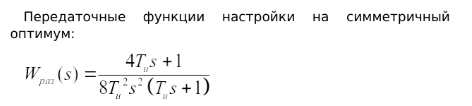

syms Tu
T1 = Tu;
Wob = Kob/(T1*s+1)/(T2*s+1)

$$Wob = \frac{\mathrm{Kob}}{\left(T_{2}\,s+1\right)\,\left(\mathrm{Tu}\,s+1\right)}$$

wol = (4*Tu*s+1)/(8*Tu^2*s^2*(Tu*s+1));
Wreg = wol/Wob;
disp(simplify(collect(Wreg, s)))

$$\frac{\left(T_{2}\,s+1\right)\,\left(4\,\mathrm{Tu}\,s+1\right)}{8\,\mathrm{Kob}\,{\mathrm{Tu}}^{2}\,s^{2}}$$

### б) Проверка формул коэффициентов

syms s T2 T1 Kob Tu 
Kpa = T2/(2*Kob*Tu);
Kia1 = 1/(2*Kob*Tu);
Kia2 = T2/(8*Kob*Tu^2);
Kiia = 1/(8*Kob*Tu^2);
Wreg0 = (Kpa*s^2+Kia1*s+Kia2*s+Kiia)/s^2
disp(simplify(collect(Wreg0,s)))

### в) Моделирование систем, настроенной на симметричный оптиум

T0 = 0.1*Tu;

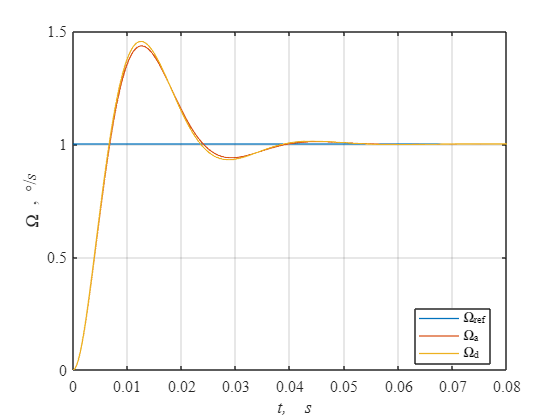

Tmdl = 0.08;
spl.Tu = ob.T1;
To = 0.1 *spl.Tu;

spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);

warning off
simNew = sim('lab5_5_1.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t = simNew.w(:,1);
w_ref = simNew.w(:,2);
wd_sens = simNew.w(:,4);

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 2.9*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 14.8*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 45.3*Tu 


T0 = 1*Tu

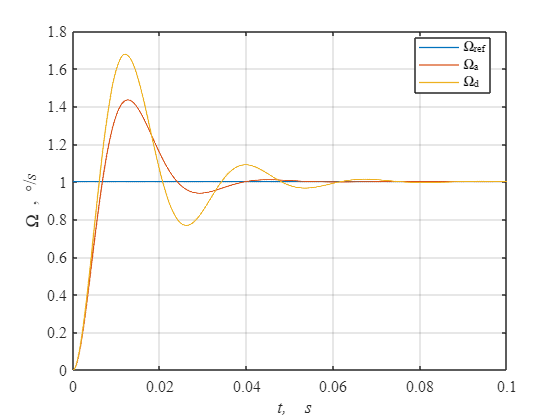

Tmdl = 0.1;
spl.Tu = ob.T1;
To = 1 *spl.Tu;


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);

warning off
simNew = sim('lab5_5_1.slx', 'ReturnWorkspaceOutputs','on');
warning on

t = simNew.w(:,1);
wref = simNew.w(:,2);
wa = simNew.w(:,3);
wd = simNew.w(:,4);

h=figure;
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');

plot(t,wref,'Linewidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t = simNew.w(:,1);
w_ref = simNew.w(:,2);
wd_sens = simNew.w(:,4);

Время переходного процесса для входа tp1 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)<D5;
tn = t(ind);
t_tr = tn(1)-t0;
fprintf('Время переходного процесса tp1 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp1 в 5% зоны: 2.7*Tu 


Время переходного процесса для входа tp2 в 5% зону

t0 = t(1);
y = wd_sens;
y0 = wd_sens(1);
yss = wd_sens(end);

D5 = 0.05*abs(yss-y0);
ind = abs(y-yss)>D5;
tn = t(ind);
t_tr = tn(end)-t0;
fprintf('Время переходного процесса tp2 в 5%% зоны: %.1f*Tu \n', t_tr/spl.Tu)

Время переходного процесса tp2 в 5% зоны: 20.2*Tu 


Перерегулирование:

dy = abs(max(y)-yss)/abs(y0-yss);
fprintf('Перерегулирование: %.1f*Tu \n', dy*100)

Перерегулирование: 67.5*Tu 


#### г) Апроксимация апереодическим звеном

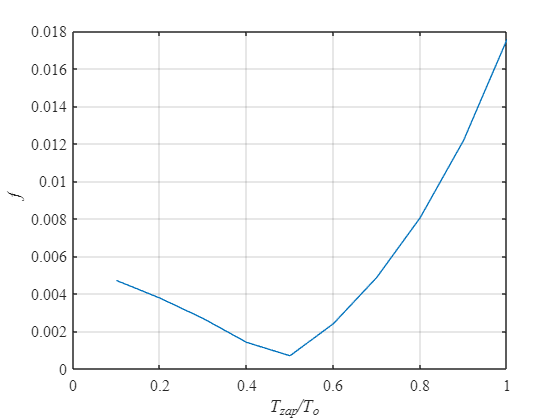

clear f Tzap
Tmdl = 0.2;
for i=1:10
    spl.Tz=i/10*To;
    Tzap(i) = spl.Tz;
    warning off
    b = sim('lab5_5_2.slx','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));
end 
h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on

xlabel('\it T_{zap}/T_o')
ylabel('\it f')

г) Синтез цифрового ПИ-регулятора методом переоборудования

T0 = 1 *T1

Tmdl = 0.1;
To = 1 *ob.T1;

spl.Tz = 0.5*To;
spl.Tu = ob.T1 + spl.Tz

spl = struct with fields:
       Tu: 0.0033
      Kpa: 5.4672e+03
      Kia: 39.8325
      Kpd: 5.4672e+03
      Kid: 39.8325
       Tz: 0.0011
      Tur: 2.1908e-04
     Kpa2: 1
     Kda2: 0.0022
    Kd2dg: 4.5167
    Kp2dg: 1
     Kia1: 20.9645
     Kia2: 1.6418e+06
     Kiia: 6.2955e+03
     Kid1: 20.9645
     Kid2: 1.6418e+06
     Kiid: 6.2955e+03


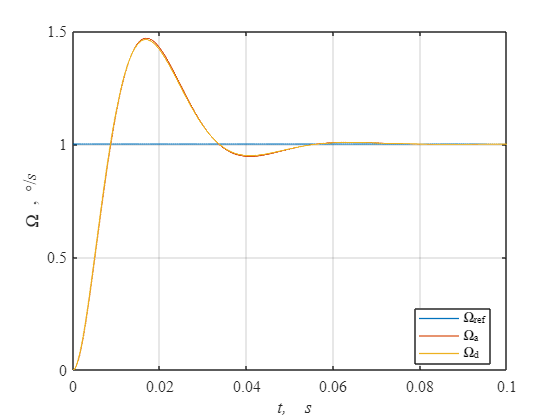


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);


warning off
b = sim('lab5_5_2.slx','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t переходного прцоесса tp1 5% зона -первое пересечение

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 2.5*Tu

t переходного прцоесса tp2 5% зона - последнее значение за пределами 5% зоны

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 12.8*Tu

dy = abs(max(y)-yss)/abs(yss-y0)

dy = 0.4619

fprintf('Перерегулирование: %.1f%%\n',dy*100) 

Перерегулирование: 46.2%


T0 = 2 *T1

Tmdl = 0.1;
To = 2 *ob.T1;

spl.Tz = 0.5*To;
spl.Tu = ob.T1 + spl.Tz

spl = struct with fields:
       Tu: 0.0044
      Kpa: 5.4672e+03
      Kia: 39.8325
      Kpd: 5.4672e+03
      Kid: 39.8325
       Tz: 0.0022
      Tur: 2.1908e-04
     Kpa2: 1
     Kda2: 0.0022
    Kd2dg: 4.5167
    Kp2dg: 1
     Kia1: 20.9645
     Kia2: 1.6418e+06
     Kiia: 6.2955e+03
     Kid1: 20.9645
     Kid2: 1.6418e+06
     Kiid: 6.2955e+03


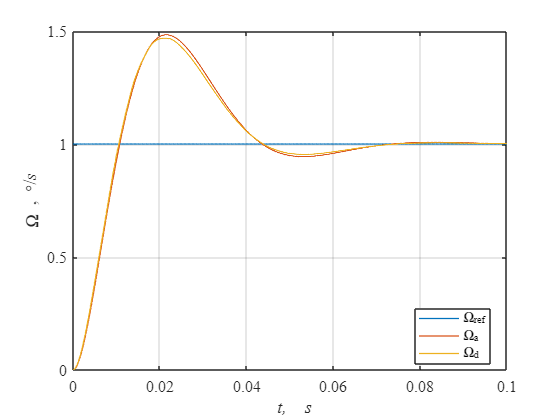


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);

spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);


warning off
b = sim('lab5_5_2.slx','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t переходного прцоесса tp1 5% зона -первое пересечение

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 2.3*Tu

t переходного прцоесса tp2 5% зона - последнее значение за пределами 5% зоны

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 9.2*Tu

dy = abs(max(y)-yss)/abs(yss-y0)

dy = 0.4667

fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 46.7%


## ** Задание 6. Синтез системы из условия получения в ней стандартной настройки на «оптимум по модулю» с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового регулятора для случая Т1 >> Т****0****,**  **Т****2 ****>> Т****0 ****, ε = 0.**

### ** a) Синтез регулятора скорости**

syms Tu T1
Wob = Kob/(T1*s+1)/(T2*s+1);
Wol = (4*Tu*s+1)/(8*Tu^2*s^2*(Tu*s+1));
Wreg = Wol/Wob;
disp(simplify(collect(Wreg,s)))

$$\frac{\left(T_{1}\,s+1\right)\,\left(T_{2}\,s+1\right)\,\left(4\,\mathrm{Tu}\,s+1\right)}{8\,\mathrm{Kob}\,{\mathrm{Tu}}^{2}\,s^{2}\,\left(\mathrm{Tu}\,s+1\right)}$$

### б) моделирование работы системы  настроенной на "cимметричный оптимум"

Tmdl = 0.015;

To = 0.1 *ob.T1;
spl.Tur = 0.5*To;
spl.Tu = spl.Tur

spl = struct with fields:
       Tu: 1.0954e-04
      Kpa: 5.4672e+03
      Kia: 39.8325
      Kpd: 5.4672e+03
      Kid: 39.8325
       Tz: 0.0022
      Tur: 1.0954e-04
     Kpa2: 1
     Kda2: 0.0022
    Kd2dg: 4.5167
    Kp2dg: 1
     Kia1: 20.9645
     Kia2: 1.6418e+06
     Kiia: 6.2955e+03
     Kid1: 20.9645
     Kid2: 1.6418e+06
     Kiid: 6.2955e+03


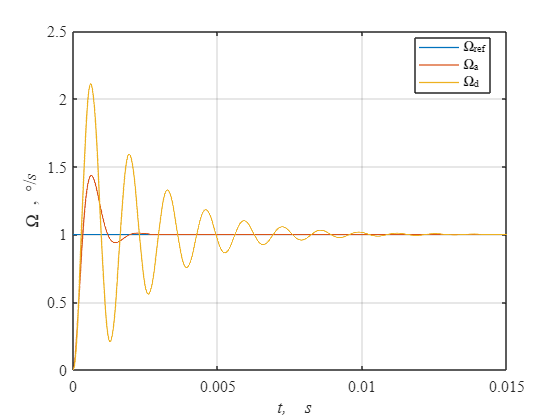


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);
spl.Kpa2 = 1;
spl.Kda2 = ob.T1;


spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);
spl.Kd2dg = 1/(exp(To/ob.T1)-1);
spl.Kp2dg = 1;


warning off
b = sim('lab5_6_1','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t переходного прцоесса tp1 5% зона -первое пересечение

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 2.5*Tu

t переходного прцоесса tp2 5% зона - последнее значение за пределами 5% зоны

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 66.8*Tu

dy = abs(max(y)-yss)/abs(yss-y0)

dy = 1.1073

fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 110.7%


### в) Апроксимация

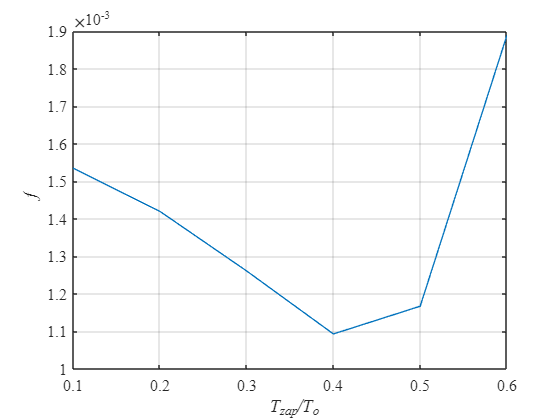

clear f Tzap
Tmdl = 0.1;
for i=1:6
    spl.Tz=i/10*To;
    Tzap(i) = spl.Tz;
    warning off
    b = sim('lab5_6_1_1.slx','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));
end 
h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on

xlabel('\it T_{zap}/T_o')
ylabel('\it f')

#### Синтез цифрового ПД ПИ регулятора скорости методом переоборудования.

T0 = 0.2*T1

Tmdl = 0.01;

To = 0.2 *ob.T1;
spl.Tz = 0.4*To;
spl.Tur = 0.5*To;
spl.Tu = spl.Tur + spl.Tz

spl = struct with fields:
       Tu: 3.9435e-04
      Kpa: 5.4672e+03
      Kia: 39.8325
      Kpd: 5.4672e+03
      Kid: 39.8325
       Tz: 1.7527e-04
      Tur: 2.1908e-04
     Kpa2: 1
     Kda2: 0.0022
    Kd2dg: 4.5167
    Kp2dg: 1
     Kia1: 20.9645
     Kia2: 1.6418e+06
     Kiia: 6.2955e+03
     Kid1: 20.9645
     Kid2: 1.6418e+06
     Kiid: 6.2955e+03


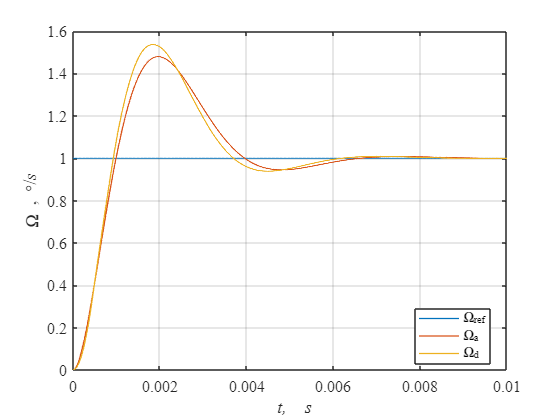



spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);
spl.Kpa2 = 1;
spl.Kda2 = ob.T1;


spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);
spl.Kd2dg = 1/(exp(To/ob.T1)-1);
spl.Kp2dg = 1;


warning off
b = sim('lab5_6_1_1.slx','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t переходного прцоесса tp1 5% зона -первое пересечение

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 2.3*Tu

t переходного прцоесса tp2 5% зона - последнее значение за пределами 5% зоны

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 12.5*Tu

dy = abs(max(y)-yss)/abs(yss-y0)

dy = 0.5372

fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 53.7%


## Задание 7. Синтез системы из условия получения в ней стандартной настройки на «симметричный оптимум» с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового регулятора для случая Т1 >> Т0, Т2 >> Т0 , ε = Т0

### а) Апроксимация

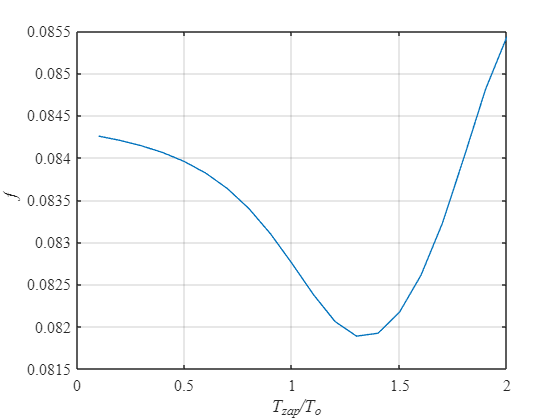

Tmdl = 0.05;
for i=1:20
    spl.Tz=i/10*To;
    Tzap(i) = spl.Tz;
    warning off
    b = sim('lab5_7.slx','ReturnWorkspaceOutputs', 'on') ;
    warning on

    t = b.w(:,1);
    wa = b.w(:,3);
    wd = b.w(:,4);
    f(i)=trapz(t,abs(wd-wa));
end 
h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(Tzap/To,f,'LineWidth', 1)
hold on
grid on

xlabel('\it T_{zap}/T_o')
ylabel('\it f')

### Синтез цифрового ПД ПИ регулятора скорости методом переоборудования.

T0 = 0.1*T1

Tmdl = 0.025;

To = 0.2 *ob.T1;
spl.Tz = 1.4*To;
spl.Tur = 0.5*To;
spl.Tu = spl.Tur + spl.Tz

spl = struct with fields:
       Tu: 8.3252e-04
      Kpa: 5.4672e+03
      Kia: 39.8325
      Kpd: 5.4672e+03
      Kid: 39.8325
       Tz: 6.1343e-04
      Tur: 2.1908e-04
     Kpa2: 1
     Kda2: 0.0022
    Kd2dg: 4.5167
    Kp2dg: 1
     Kia1: 20.9645
     Kia2: 1.6418e+06
     Kiia: 6.2955e+03
     Kid1: 20.9645
     Kid2: 1.6418e+06
     Kiid: 6.2955e+03


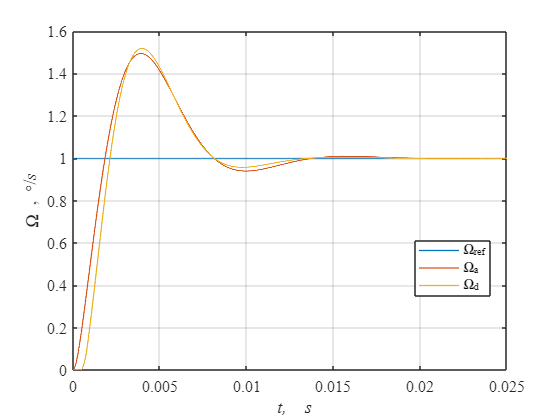


spl.Kpa = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kia1 = 1/(2*ob.Kob*spl.Tu);
spl.Kia2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiia = 1/(8*ob.Kob*spl.Tu^2);
spl.Kpa2 = 1;
spl.Kda2 = ob.T1;




spl.Kpd = ob.T2/(2*ob.Kob*spl.Tu);
spl.Kid1 = 1/(2*ob.Kob*spl.Tu);
spl.Kid2 = ob.T2/(8*ob.Kob*spl.Tu^2);
spl.Kiid = 1/(8*ob.Kob*spl.Tu^2);
spl.Kd2dg = 1/(exp(To/ob.T1)-1);
spl.Kp2dg = 1;


warning off
b = sim('lab5_7','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t переходного прцоесса tp1 5% зона -первое пересечение

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 2.5*Tu

t переходного прцоесса tp2 5% зона - последнее значение за пределами 5% зоны

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 9.0*Tu

dy = abs(max(y)-yss)/abs(yss-y0)

dy = 0.5177

fprintf('Перерегулирование: %.1f%%\n',dy*100)

Перерегулирование: 51.8%
